# Curve Parametriche

Nel caso in cui io voglia trovare la parametrizzazione di una curva, dovrò trovare due polinomi che gestiscano x e y

## Esempio curva parametrica

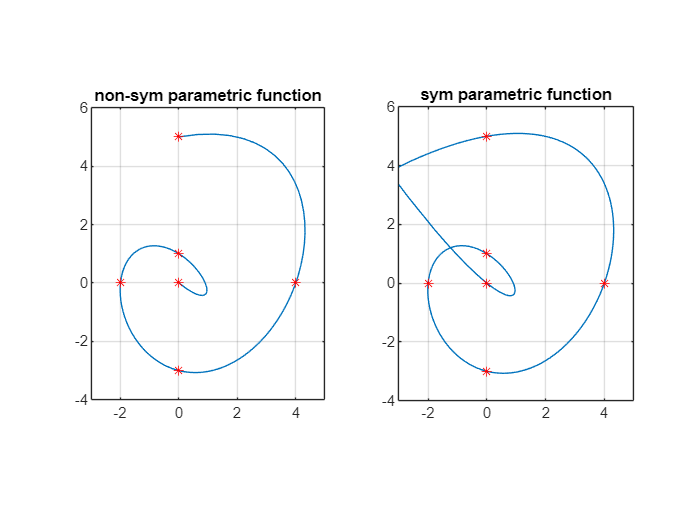

X = [0 0 -2  0 4 0];
Y = [0 1  0 -3 0 5];

gradoPoly = length(X) - 1;  % il grado di px(t) e py(t)
indici_t  = 0 : gradoPoly;  % sarà la nostra 't' per X e Y

coeffP_x = polyfit(indici_t, X, gradoPoly);
coeffP_y = polyfit(indici_t, Y, gradoPoly);


% versione non-simbolica
t   = linspace(0, max(indici_t));
p_x = polyval(coeffP_x, t); 
p_y = polyval(coeffP_y, t);

subplot(1,2,1), plot(p_x, p_y);
    title("non-sym parametric function")
    grid on, axis equal, xlim([-3 5]), ylim([-4 6])
    hold on, plot(X,Y,'r*'), hold off


% versione simbolica
syms t_s
p_x = poly2sym(coeffP_x, t_s); 
p_y = poly2sym(coeffP_y, t_s);

subplot(1,2,2), fplot(p_x, p_y, [-3, 6]);
    title("sym parametric function")
    grid on, axis equal, xlim([-3 5]), ylim([-4 6])
    hold on, plot(X,Y,'r*'), hold off